## Open Loop Transfer Function

G =tf([1, 1], [1, 1, 4])

G =
 
     s + 1
  -----------
  s^2 + s + 4
 
Continuous-time transfer function.



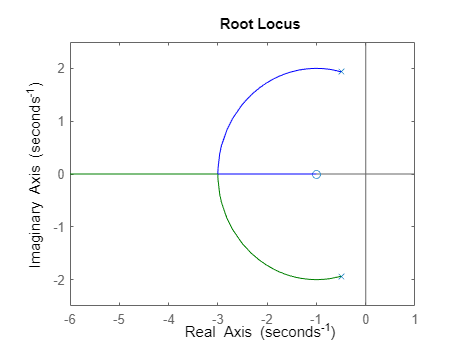

rlocus(G)

## Unity Gain Feedback

F = feedback(G, 1)

F =
 
      s + 1
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.



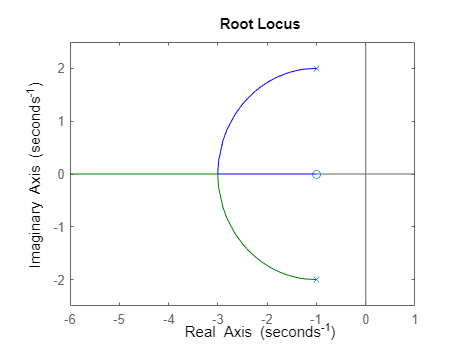

rlocus(F)

## Proportional Control

Kp = 2

Kp = 2

F = feedback(Kp*G, 1)

F =
 
     2 s + 2
  -------------
  s^2 + 3 s + 6
 
Continuous-time transfer function.



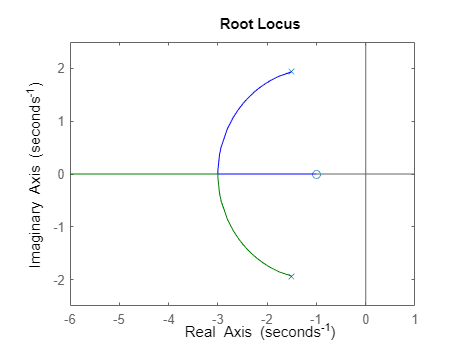

rlocus(F)

## Proportional-Derivative Control

Kd = 1

Kd = 1

C = tf([Kd, Kp],[1])

C =
 
  s + 2
 
Continuous-time transfer function.



F = feedback(C*G, 1)

F =
 
   s^2 + 3 s + 2
  ---------------
  2 s^2 + 4 s + 6
 
Continuous-time transfer function.



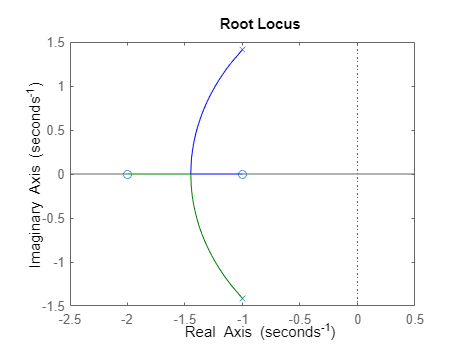

rlocus(F)

## PID Control

F =  tf([1, 3, 3, 1],[2, 4, 7, 1])

F =
 
   s^3 + 3 s^2 + 3 s + 1
  -----------------------
  2 s^3 + 4 s^2 + 7 s + 1
 
Continuous-time transfer function.



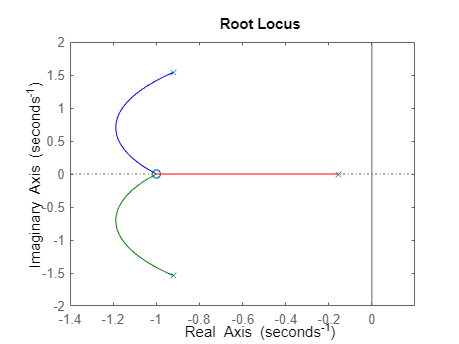

rlocus(F)